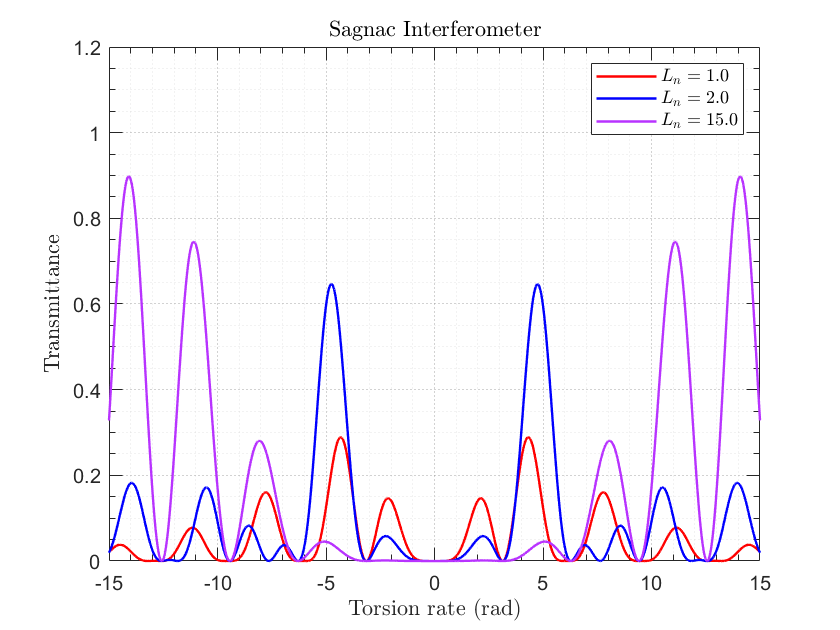

clc;
close all;
clear;

cd C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab


% Define constants
lambda = 1550e-9;  % Wavelength (m)
alpha = 0.5;       % Coupler rate
Lb = 1;            % Beat length (m)
g = 0.16;          % Silica fiber parameter
t = -15:0.01:15;   % Torsion values (rad)
psi0 = 0;          % Fiber main axis rotation angle
theta = 0;         % Port 3 fiber main axis rotation angle
DeltaN = lambda / Lb;  % Estimated birefringence
L1 = 1;            % Arm length B1
L2 = 1;            % Arm length B2
t1 = 0;            % Arm torsion B1
t2 = 0;            % Arm torsion B2
E1 = [1; 0];       % Input field (Jones vector)
Iin = norm(E1)^2;  % Input intensity

% Different normalized fiber lengths
Ln_values = [1, 2, 15];
colors = {'r', 'b', '#b833ff'}; % Colors for each plot
labels = arrayfun(@(Ln) sprintf('$L_n = %.1f$', Ln), Ln_values, 'UniformOutput', false);

figure;
hold on;

for i = 1:length(Ln_values)
    Ln = Ln_values(i);
    I_out = SagnacTorsionFunction(t, lambda, L1, DeltaN, g, t1, L2, t2, theta, psi0, Ln, E1, alpha);
    T = I_out / Iin;
    plot(t, T, 'LineWidth', 1.2, 'Color', colors{i}, 'DisplayName', labels{i});
end

xlabel('Torsion rate (rad)', 'Interpreter', 'latex');
ylabel('Transmittance', 'Interpreter', 'latex');
title('Sagnac Interferometer', 'Interpreter', 'latex');
grid on;
legend('show', 'Interpreter', 'latex');

set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickLength', [0.02, 0.04], 'LineWidth', 0.5);
grid minor;
set(gca, 'GridLineStyle', ':', 'GridColor', [0.5, 0.5, 0.5], 'GridAlpha', 0.7, ...
         'MinorGridLineStyle', ':', 'MinorGridColor', [0.8, 0.8, 0.8], 'MinorGridAlpha', 0.5);
ylim([0 1.2])

box on
hold off;

fig_save = gcf();
exportgraphics(fig_save, 'SagnaPlots1to15.pdf')

function I_out = SagnacTorsionFunction(t, lambda, L1, DeltaN, g, t1, L2, t2, theta, psi0, Ln, E1, alpha)
    I_out = zeros(1, length(t));

    for i = 1:length(t)
        delta_lb1 = (2*pi/lambda) * (L1 * DeltaN);
        delta_c1  = (1 - g/2) * t1;
        delta_lb2 = (2*pi/lambda) * (L2 * DeltaN);
        delta_c2  = (1 - g/2) * t2;

        etaB1 = etaBn(delta_lb1, delta_c1);
        etaB2 = etaBn(delta_lb2, delta_c2);
        P1 = Pn(etaB1, delta_lb1);
        P2 = Pn(etaB2, delta_lb2);
        Q1 = Qn(etaB1, delta_c1);
        Q2 = Qn(etaB2, delta_c2);
        B1 = BnMat(P1, Q1);
        B2 = BnMat(P2, Q2);

        C1 = C1Mat(theta);
        C2 = C2Mat(psi0, Ln, t(i));

        delta_cL = (1 - g/2) * t(i);
        etaFL = etaL(psi0, Ln, delta_cL);
        PFL = PL(etaFL, Ln);
        QFL = QL(psi0, Ln, delta_cL, etaFL);
        FL = FLMat(PFL, QFL);

        J = B1 * C1 * FL * C2 * B2;
        E2 = Eout(E1, J, alpha);
        I_out(i) = norm(E2)^2;
    end
end

function C1 = C1Mat(theta)
    C1 = [cos(theta), -sin(theta); sin(theta), cos(theta)];
end

function C2 = C2Mat(psi0, Ln, t)
    C2 = [cos(psi0*Ln + t), -sin(psi0*Ln + t); sin(psi0*Ln + t), cos(psi0*Ln + t)];
end

function B = BnMat(P, Q)
    B = [P, conj(Q); Q, conj(P)];
end

function P = Pn(etaB, delta_lb)
    P = cos(etaB) - 1j * (delta_lb / 2) * (sin(etaB) / etaB);
end

function Q = Qn(etaB, delta_c)
    Q = delta_c * (sin(etaB) / etaB);
end

function etaB = etaBn(delta_lb, delta_c)
    etaB = sqrt((delta_lb/2)^2 + delta_c^2);
end

function FL = FLMat(P, Q)
    FL = [P, conj(Q); -Q, conj(P)];
end

function P = PL(eta, Ln)
    P = cos(eta) - pi * 1j * Ln * (sin(eta) / eta);
end

function Q = QL(psi0, Ln, delta_c, eta)
    Q = (psi0 * Ln + delta_c) * (sin(eta) / eta);
end

function eta = etaL(psi0, Ln, delta_c)
    eta = sqrt((pi * Ln)^2 + (psi0 * Ln + delta_c)^2);
end

function E2 = Eout(E1, J, alpha)
    Jxx = J(1,1);
    Jxy = J(1,2);
    Jyx = J(2,1);
    E2 = [ (2*alpha-1)*Jxx, (1-alpha)*Jxy + alpha*Jyx;
           -alpha*Jxy - (1-alpha)*Jyx, (1-2*alpha)*Jxx ] * E1;
end
